# `Demo_01:`    Steady State Heat Transfer Analysis **- Finite Difference**

In this example we'll perform a **Steady State Thermal analysis** of a roof cavity insulation system typically found in residential houses.  The scenario that we'll consider is shown below:

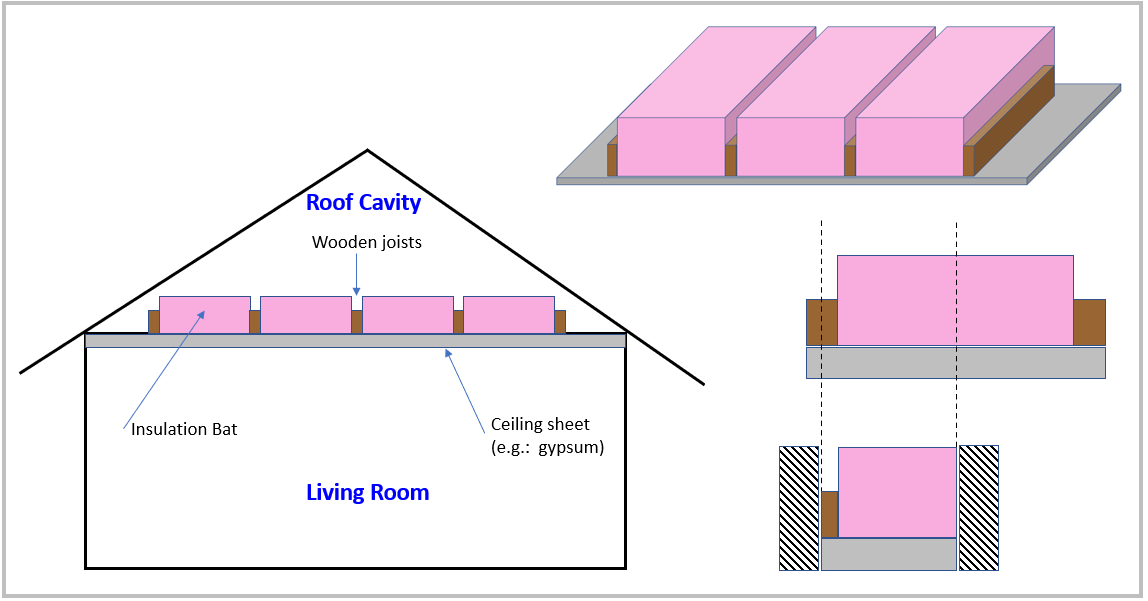

**History:**

- `19-Jul-2021: Created (bhorton@mathworks.com) `

## Problem Description:

We'll implement a first principles **Finite Difference** approach to solve a 2D Thermal Analysis problem.   **Finite Difference stencils** are computed based on an energy balance(conduction and convection) for a control surface around each different node type(see specifically [`bh_get_node_stencils`](matlab: edit bh_get_node_stencils)), eg:

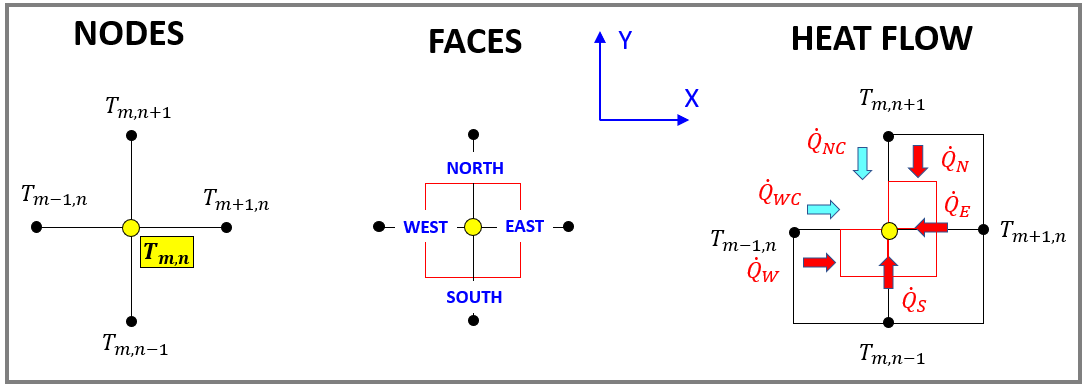

This script presents the Steady state thermal analysis of an insulation system installed in the roof cavity of a domestic house.  The system being considered is shown in the figure below - NOTE Point $\mathit{\mathbf{O}}$ is the "origin" for our spatial domain.  Key components of the system include:

- Block **A** :    a **Ceiling** sheet

- Block **B** :    a **Joist**

- Block **C** :    a Thermal insulation **Batt**

**System Boundary Conditions**

- Conduction in the X-direction through the EAST face of the  **Batt** is ZERO (a **symmetry condition**)

- Conduction in the X-direction through the WEST face of the  **Joist** is ZERO (a **symmetry condition**)

- Convection is possible in the Roof cavity (**Joist, Batt**)

- Convection is possible in the Living space (**Ceiling**)

**Co-ordinates and Node Labelling convention:**

- Point $\mathit{\mathbf{O}}$ is the "origin" for our spatial domain

- ${\textrm{NODE}}_{\;i\;,j}$ has a spatial co-ordinate of $\left(i\ldotp \Delta x\;,j\ldotp \Delta y\right)$

- ${\textrm{NODE}}_{\;i\;,j}$ has a Temperature of $T_{\;i\;,j}$

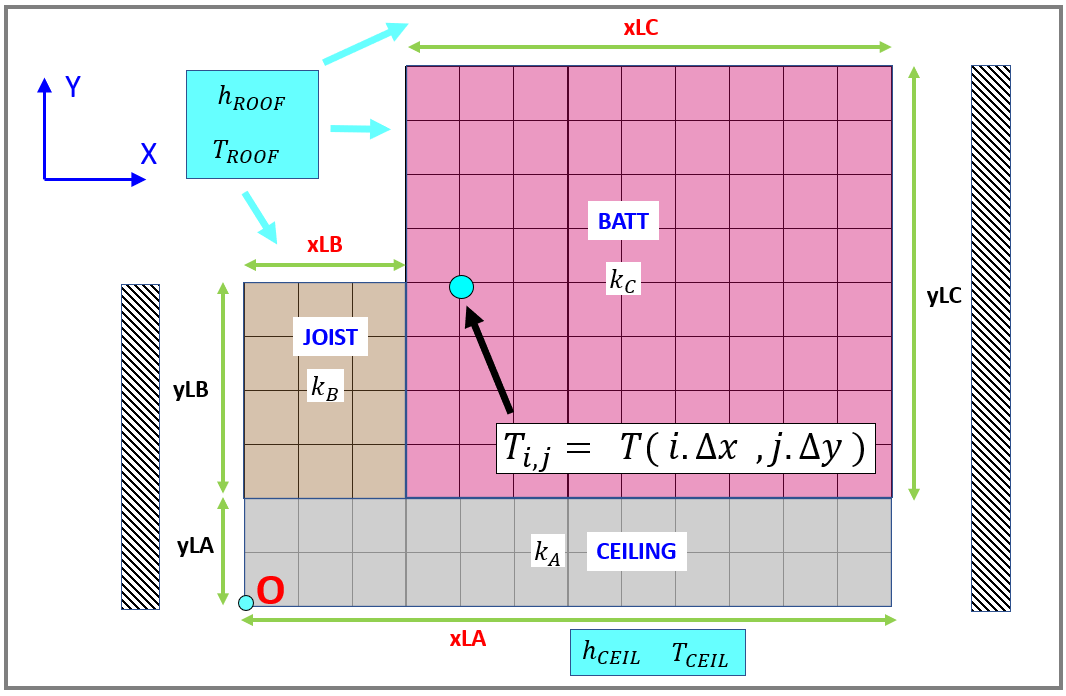

## **Load Thermal and Geometric parameters**

Thermal and geometry parameters for this system are defined in an EXCEL file [**bh_PARAMS_DATABASE.xlsx**](matlab: winopen(pwd  + string(filesep) + "bh_PARAMS_DATABASE.xlsx")).  So let's read this data in.

- **NOTE**:  The physical widths of the BATT and JOIST as expressed in the EXCEL file ... are halved when they are assigned to our geometry fields **xLB, xLC ...** because our thermal analysis applies symmetry boundary conditions at the joist and batt.

OBJ_params = bh_sys_params_CLS("bh_PARAMS_DATABASE.xlsx", "SET_1")

OBJ_params =   bh_sys_params_CLS with properties:

     Filename: "bh_PARAMS_DATABASE.xlsx"
    Sheetname: "SET_1"
       my_tab: [19×5 table]
          k_A: 0.1700
          k_B: 0.1200
          k_C: 0.0488
       h_ROOF: 4
       h_CEIL: 1.3000
       T_ROOF: 55
       T_CEIL: 25
          xLA: 0.3000
          xLB: 0.0175
          xLC: 0.2825
          yLA: 0.0130
          yLB: 0.0900
          yLC: 0.1950
         Nx_A: []
         Nx_B: []
         Nx_C: []
         Ny_A: []
         Ny_B: []
         Ny_C: []
      Delta_X: []
      Delta_Y: []


## **Define the Finite Difference interval lengths between nodes:**

Set the Finite Difference interval widths $\Delta x$ and $\Delta y$ 

**NOTE**: 

- For this problem try $\Delta =0\ldotp 003$ first ... as this solves relatively quickly

- A value of  $\Delta =0\ldotp 001$ can also be used ... but will take approx 1-2 minutes to solve on a Lenovo P53 laptop

my_dx      = 0.003;
my_dy      = my_dx;
OBJ_params = OBJ_params.set_deltas(my_dx, my_dy)

--------------------------------------------------
 TESTING discretization on component lengths 
--------------------------------------------------
 ... xLA diff =  0.0000 (m), [ 0.3000 --->  0.3000]
 ... xLB diff =  0.0005 (m), [ 0.0175 --->  0.0180]
 ... xLC diff =  0.0005 (m), [ 0.2825 --->  0.2820]
 ... yLA diff =  0.0010 (m), [ 0.0130 --->  0.0120]
 ... yLB diff =  0.0000 (m), [ 0.0900 --->  0.0900]
 ... yLC diff =  0.0000 (m), [ 0.1950 --->  0.1950]
--------------------------------------------------


OBJ_params =   bh_sys_params_CLS with properties:

     Filename: "bh_PARAMS_DATABASE.xlsx"
    Sheetname: "SET_1"
       my_tab: [19×5 table]
          k_A: 0.1700
          k_B: 0.1200
          k_C: 0.0488
       h_ROOF: 4
       h_CEIL: 1.3000
       T_ROOF: 55
       T_CEIL: 25
          xLA: 0.3000
          xLB: 0.0175
          xLC: 0.2825
          yLA: 0.0130
          yLB: 0.0900
          yLC: 0.1950
         Nx_A: 100
         Nx_B: 6
         Nx_C: 94
         Ny_A: 4
         Ny_B: 30
         Ny_C: 65
      Delta_X: 0.0030
      Delta_Y: 0.0030


The number of finite difference intervals in the $X$and $Y$directions has also been computed for the 3 "Blocks" of our system, eg:

- Block A has LOCAL nodes in the $X$ direction that are labelled $0\;\;,\;1\;\;,\;\;2\;\;,\;3\;\;,\;\cdots N_{\textrm{XA}}$ 

- Block A has LOCAL nodes in the $Y$ direction that are labelled $0\;\;,\;1\;\;,\;\;2\;\;,\;3\;\;,\;\cdots N_{\textrm{YA}}$ 

- And we have the relationship that:   $\textrm{xLA}\;=\;N_{\textrm{XA}} \;\times \Delta x$   and   $\textrm{yLA}\;=\;N_{\textrm{YA}} \;\times \Delta y$

- etc for Blocks B and C

**NOTE**:

- We'll discuss node geometry more in one of the NEXT sections

- The reason for introducing the concept of $\Delta x$ and $\Delta y$ now ... is because these values are needed in order to compute the Finite Difference stencils that are introduced in the next section.

## Compute the Finite Difference STENCILS for the different NODE types

For our specific problem there are ***23 different NODE types***.  For example see below.  The labels for these different node types are defined in the file [`bh_fd_node_type_ENUM.m`](matlab:  edit bh_fd_node_type_ENUM.m).  The function [`bh_get_node_stencils`](matlab: edit bh_get_node_stencils) does a STEADY STATE thermal analysis for each of these different node types. The class [`bh_fd_stencil_CLS`](matlab:  edit bh_fd_stencil_CLS) will be the data container that we use to manage the access to these thermal stencils.

- **NOTE**:  The real **ENGINEERING** for this problem is documented in the function [`bh_get_node_stencils`](matlab: edit bh_get_node_stencils) where we do a steady state heat flow rate analysis on each different node type. So? - so please check it out.

- **NOTE**:  To explore the concept used here, explore the TEST script [**bh_test_stencil**](matlab: edit bh_test_stencil)

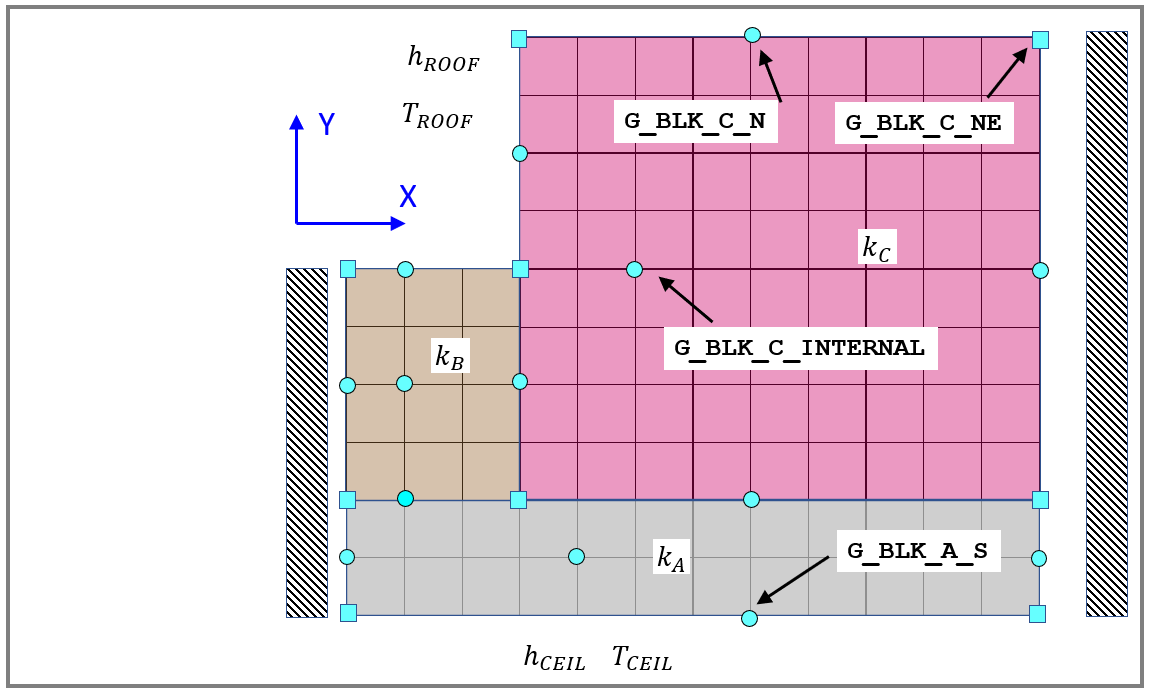

OBJ_fd_stencils = bh_fd_stencil_CLS(OBJ_params)


 ... Finished [ 1] of 23 :  NODE_TYPE = G_BLK_B_INTERNAL
 ... Finished [ 2] of 23 :  NODE_TYPE = G_BLK_B_NW
 ... Finished [ 3] of 23 :  NODE_TYPE = G_BLK_B_N
 ... Finished [ 4] of 23 :  NODE_TYPE = G_BLK_B_NE
 ... Finished [ 5] of 23 :  NODE_TYPE = G_BLK_B_E
 ... Finished [ 6] of 23 :  NODE_TYPE = G_BLK_B_SE
 ... Finished [ 7] of 23 :  NODE_TYPE = G_BLK_B_S
 ... Finished [ 8] of 23 :  NODE_TYPE = G_BLK_B_SW
 ... Finished [ 9] of 23 :  NODE_TYPE = G_BLK_B_W
 ... Finished [10] of 23 :  NODE_TYPE = G_BLK_C_INTERNAL
 ... Finished [11] of 23 :  NODE_TYPE = G_BLK_C_W
 ... Finished [12] of 23 :  NODE_TYPE = G_BLK_C_NW
 ... Finished [13] of 23 :  NODE_TYPE = G_BLK_C_N
 ... Finished [14] of 23 :  NODE_TYPE = G_BLK_C_NE
 ... Finished [15] of 23 :  NODE_TYPE = G_BLK_C_E
 ... Finished [16] of 23 :  NODE_TYPE = G_BLK_C_SE
 ... Finished [17] of 23 :  NODE_TYPE = G_BLK_C_S
 ... Finished [18] of 23 :  NODE_TYPE = G_BLK_A_INTERNAL
 ... Finished [19] of 23 :  NODE_TYPE = G_BLK_A_SW
 ... Finished [20] o

OBJ_fd_stencils =   bh_fd_stencil_CLS with properties:

    tab: [23×15 table]


The main data component for this object is the table:

OBJ_fd_stencils.tab

ans = 23×15 table
                           node_type_fd                                                                                                                                      s_A                                                                                                                                                              s_b                                                                                  s_x                                                                                                                  str_x                                                               T_mM1_nP1     T_m_nP1     T_mP1_nP1     T_mM1_n      T_m_n      T_mP1_n     T_mM1_nM1     T_m_nM1     T_mP1_nM1     b  
   

**NOTE**:  The table has been designed so that you can use the node type as a mechanism to access the rows of the table

OBJ_fd_stencils.tab("G_BLK_B_N", :)

ans = 1×15 table
                 node_type_fd                                                                                           s_A                                                                                                      s_b                                                                  s_x                                                                                                                  str_x                                                               T_mM1_nP1    T_m_nP1    T_mP1_nP1    T_mM1_n    T_m_n    T_mP1_n    T_mM1_nM1    T_m_nM1    T_mP1_nM1     b  
                 ____________    _________________________________________________________________________________

## Create the Node Blocks

Now let's create nodes for each of our 3 blocks

-  **Block A **is the **CEILING** sheet (eg: Gypsum)

-  **Block B** is the **JOIST** 

-  **Block C** is the **BATT**  

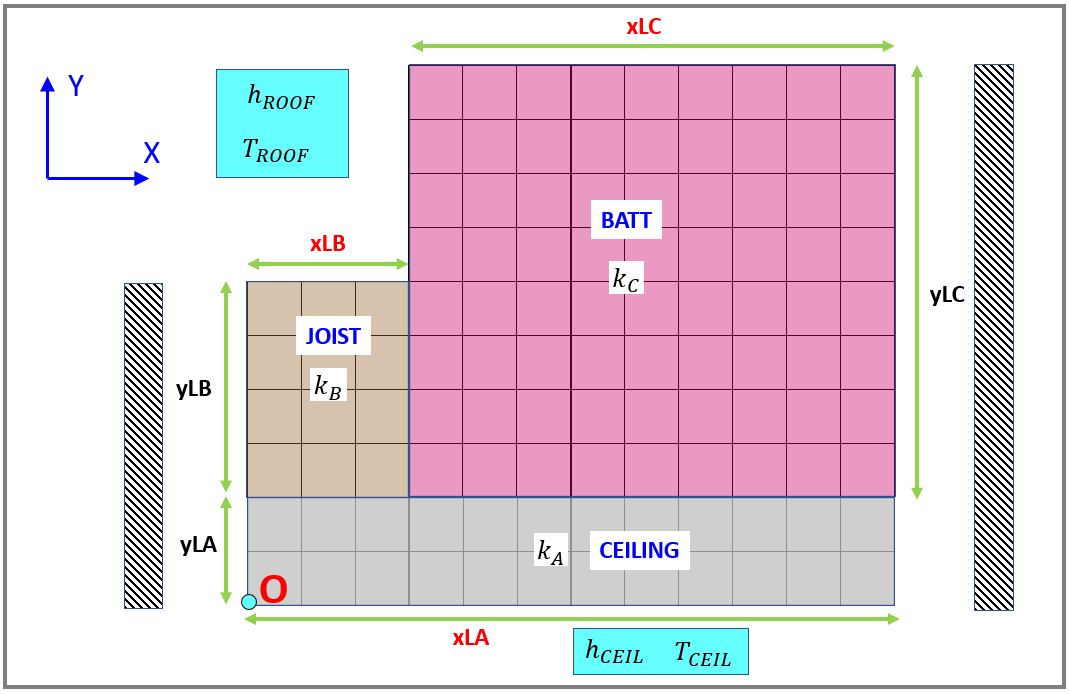

A block is characterised by the number of nodes in the $X$and $Y$ directions as well as any offsets that allow us to compute GLOBAL node co-ordinates, eg:

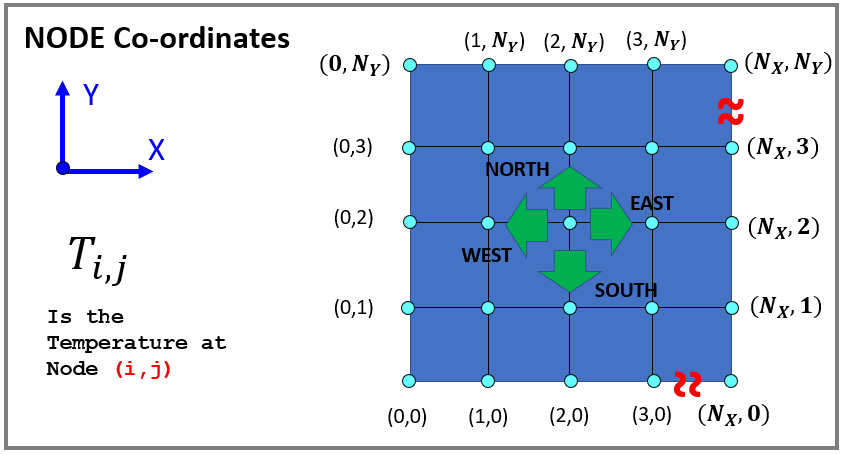  

**NOTE**:  To explore the concept used here, explore the TEST script [**bh_test_block**](matlab: edit bh_test_block)

block_A = bh_block_CLS(OBJ_params.Nx_A, OBJ_params.Ny_A, ...
                       "i_offset",0, ...
                       "j_offset",0);

block_B = bh_block_CLS(OBJ_params.Nx_B, OBJ_params.Ny_B, ...
                       "i_offset",0, ...
                       "j_offset",OBJ_params.Ny_A);

block_C = bh_block_CLS(OBJ_params.Nx_C, OBJ_params.Ny_C, ...
                       "i_offset",OBJ_params.Nx_B, ...
                       "j_offset",OBJ_params.Ny_A);

And visualize the blocks

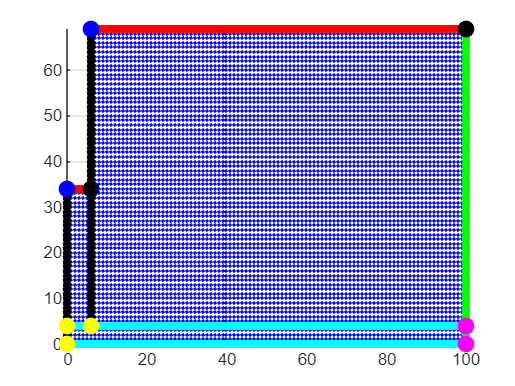

figure;
    hax = axes();
        block_A.plot("Global_ij", "Parent",hax)
        block_B.plot("Global_ij", "Parent",hax)
        block_C.plot("Global_ij", "Parent",hax)

## Create our Finite Difference mesh

Now for each node in our blocks we need to do the following:

- **Join** the blocks together - which means removing any duplicate nodes (eg: where the JOIST contacts the BATT)

- **Label** each node as belonging to ONE of the unique node types that we have computed Finite Difference stencils for.

This mesh creation step is done within the [`bh_fd_mesh_CLS`](matlab: edit bh_fd_mesh_CLS) class

OBJ_fd_mesh = bh_fd_mesh_CLS(block_A, block_B, block_C)

OBJ_fd_mesh =   bh_fd_mesh_CLS with properties:

       tab: [6860×8 table]
    T_list: [6860×1 string]
     A_sys: []
     b_sys: []
     x_sys: []


**NOTE**: Note the following about our mesh object `OBJ_fd_mesh`

- It contains fields `A_sys b_sys, x_sys` for the GLOBAL system of equations $A\ldotp x=b$.  We'll compute these next.

- The NODES in our mesh are stored in a table `tab`

- The property `T_list` is an array of strings and corresponds to the "design variables" that are represented in $x$

Here's a peak at the first few rows in our mesh table:

head(  OBJ_fd_mesh.tab  )

                i_local    j_local    i_global    j_global    is_active    node_type_blk       node_type_fd       NODE_NAME 
                _______    _______    ________    ________    _________    _____________    __________________    __________

    NODE_1_1       1          1          1           1          true        "INTERNAL"      "G_BLK_A_INTERNAL"    "NODE_1_1"
    NODE_2_1       2          1          2           1          true        "INTERNAL"      "G_BLK_A_INTERNAL"    "NODE_2_1"
    NODE_3_1       3          1          3           1          true        "INTERNAL"      "G_BLK_A_INTERNAL"    "NODE_3_1"
    NODE_4_1       4          1   

**NOTE**:

- There is a column in this table called `NODE_NAME` which defines the name(or label) of each node in the table.

- The table has been configured so that the name of the node can be used as an index into the table

- There is a column in this table called `node_type_fd` which defines the node type for each node in the table.

For example, let's look at the row in the table for the node with the name "NODE_0_0"

OBJ_fd_mesh.tab("NODE_0_0",:)

ans = 1×8 table
                i_local    j_local    i_global    j_global    is_active    node_type_blk     node_type_fd    NODE_NAME 
                _______    _______    ________    ________    _________    ______________    ____________    __________

    NODE_0_0       0          0          0           0          true       "BC_CORNER_SW"    "G_BLK_A_SW"    "NODE_0_0"


And we can visualize the mesh too - the nodes are coloured according to their node type

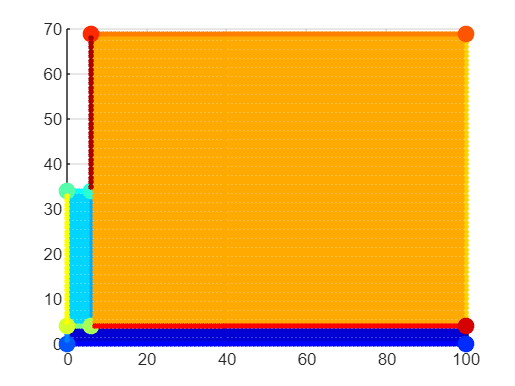

OBJ_fd_mesh.plot()

## Assemble the system `A.x=b` equations

OK, now that we have our mesh, we can assemble the GLOBAL $A\;\textrm{and}\;b$ matrices for this system.  This matrix assembly step is done by the [`assemble_sys_A_b`](matlab: edit bh_fd_mesh_CLS) method of the `OBJ_fd_mesh` object.  For each node in our mesh table, we do the following:

- get it's node type

- retrieve the finite difference stencil for that particular node type

- determine the columns of the GLOBAL $A$ matrix to populate

- NOTE:  the global $A$ matrix is a SPARSE matrix, ie: most rows in the matrix are ZEROS

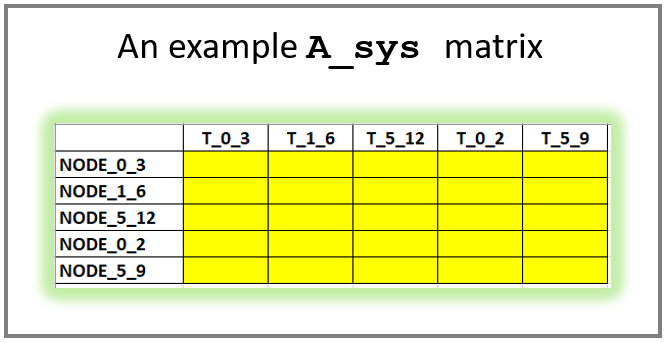

**ATTENTION:**  Assembling the system matrices will take approx 1 minute to compute for a mesh with $\Delta =0\ldotp 001$

OBJ_fd_mesh = OBJ_fd_mesh.assemble_sys_A_b(OBJ_fd_stencils)


 ... completed kk=  1000 of 6860
 ... completed kk=  2000 of 6860
 ... completed kk=  3000 of 6860
 ... completed kk=  4000 of 6860
 ... completed kk=  5000 of 6860
 ... completed kk=  6000 of 6860

OBJ_fd_mesh =   bh_fd_mesh_CLS with properties:

       tab: [6860×8 table]
    T_list: [6860×1 string]
     A_sys: [6860×6860 double]
     b_sys: [6860×1 double]
     x_sys: []


As you can see from the echo of `OBJ_fd_mesh`, our system matrices `A_sys` and `b_sys` have now been created.  Our next step is to use them to solve for `x_sys `... and we'll do that in the next section.

## Solve the system equations

Now we can solve our GLOBAL system of equations, ie:  $A\ldotp x=b\;\;\;\;\;\Longrightarrow \;\;\;\;\;x=A\backslash b$ . This is done by the `solve` method of the [`bh_fd_mesh_CLS`](matlab: edit bh_fd_mesh_CLS) class .... and is nothing more than $x=A\backslash b$

OBJ_fd_mesh = OBJ_fd_mesh.solve();

And let's retrieve the results

[T_col, mn_mat] = OBJ_fd_mesh.results_retrieve();
whos T_col mn_mat

  Name           Size             Bytes  Class     Attributes

  T_col       6860x1              54880  double              
  mn_mat      6860x2             109760  double              



## And Visualize the results - part 1

Visualize the Steady state temperature values across our mesh

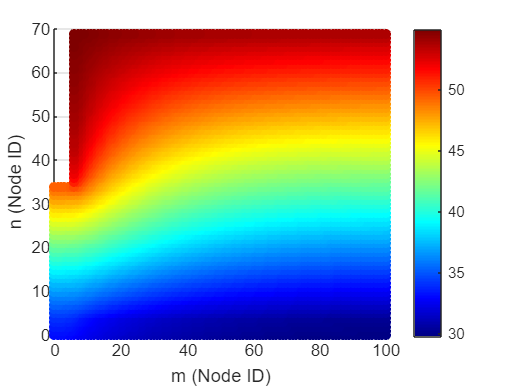

OBJ_fd_mesh.results_plot("scatter");

## And Visualize the results - part 2

Let's slice and dice.  Choose a slice direction

slice_dir = "n_slice";

The postion of the slice plane is defined by a normalized value between $0$ and $1$

tgt_fract = 0.21;

Now plot the slice

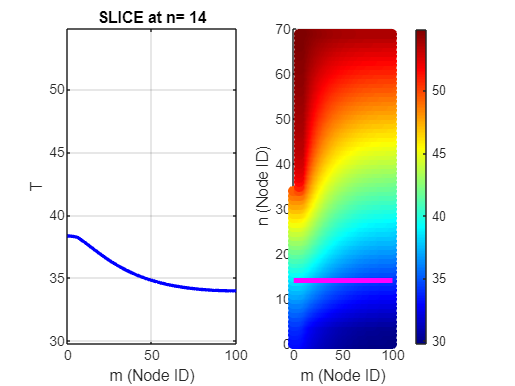


OBJ_fd_mesh.results_plot_slice( slice_dir, tgt_fract)

### Now compute the Heat flow rate flowing through the ceiling boundary

For each ceiling node on the SOUTH boundary of the ceiling block we have

- $\frac{{\dot{Q} }_{\textrm{SC}} }{L}\;=\;h_{\textrm{CEIL}} \;\;\ldotp \bar{A} \;\ldotp \left(T_{\textrm{CEIL}} -T_{m\ldotp n} \right)$       where    $\bar{A\;} \;=\;\frac{A}{L}$   and $L$ is the $Z$ axis length

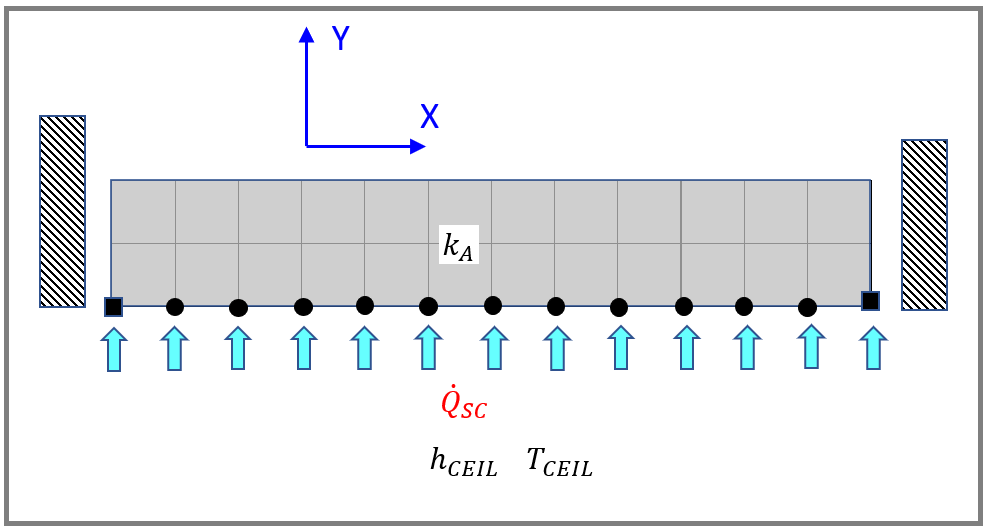

 First extract the mesh table and insert an extra column called `T_ss `that contains our steady state Temperature solution

my_tab      = OBJ_fd_mesh.tab;
my_tab.T_ss = OBJ_fd_mesh.x_sys;

Now extract rows from the mesh table that correspond to the ceiling SOUTH face boundary:

tf_ind        = my_tab.node_type_fd == "G_BLK_A_SW";
SW_corner_tab = my_tab(tf_ind,:);

tf_ind        = my_tab.node_type_fd == "G_BLK_A_SE";
SE_corner_tab = my_tab(tf_ind,:);

tf_ind        = my_tab.node_type_fd == "G_BLK_A_S";
S_face_tab    = my_tab(tf_ind,:);

mini_tab      = [SW_corner_tab;
                 SE_corner_tab;
                 S_face_tab ];

OK, let's accumulate the heat flowrate through the south face of each node:

- 
$$\frac{{\dot{Q} }_{\textrm{SC}} }{L}\;\;=\;\;\sum_m \;\;h_{\textrm{CEIL}} \;\;\ldotp \bar{A} \;\ldotp \left(T_{\textrm{CEIL}} -T_{m\ldotp n} \right)\;\;$$


Q_norm = 0;
for kk =1:height(mini_tab)
    node_type = mini_tab.node_type_fd(kk);
    switch(node_type)
        case {"G_BLK_A_SW","G_BLK_A_SE"}
              Area = OBJ_params.Delta_X/2;
        case "G_BLK_A_S"
              Area = OBJ_params.Delta_X;
        otherwise
            error("###_ERROR: This should NOT happen !");
    end
    
    Q_norm = Q_norm +  (OBJ_params.h_CEIL * Area * (OBJ_params.T_CEIL - mini_tab.T_ss(kk)));
    
end

And the answer is:

display(Q_norm)

Q_norm = -2.2097